%calculating the mean first passage time analytically/numerically 
%to investigate effect of incumbent and invader toehold lengths on DNA/RNA
%toehold exchange kinetics including spontaneous incumbent and invader
%dissociation

b = 20 %define branch migration domain length

b = 20

%g = 2 %define invader toehold length
%g2 = 4 %define incumbent toehold length

R = 1.987/1000 %universal gas constant in kcal/K/mol 

R = 0.0020

temp = 298.15 %temperature in K

temp = 298.1500

%free energy parameters
dGassoc = 2.6*R*temp 

dGassoc = 1.5403

dGbp = -2.52*R*temp

dGbp = -1.4929

dGp = 3.6*R*temp

dGp = 2.1327

dGrd = -0.2*R*temp

dGrd = -0.1185

dGbm = 7.4*R*temp 

dGbm = 4.3839

%absolute rate constant
k_bp = 5.4*10^7

k_bp = 54000000

k_eff = zeros(5,15)

k_eff =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


first_pass_time = zeros(5, 15)

first_pass_time =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


prob_unbound = zeros(5, 15)

prob_unbound =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



%loop through incumbent toehold lengths
for g2 = 2:6
    bg2 = b+ g2 %define branch migration domain + incumbent toehold length 
    %loop through invader toehold lengths 
    for g = 1:15
        g

        %define forward and reverse transition rates
        k_AA = 0;
        k_AB1 = k_bp * exp(-dGassoc/(R*temp)) * (5*10^-8)
        k_B1A = k_bp * exp(dGbp/(R*temp))
        k_BC1ij = k_bp;
        k_BC1ji = k_bp * exp(dGbp/(R*temp));
        k_C1f = k_bp * exp(-(dGbm + dGp - dGrd)/(R*temp))
        k_Cf = k_bp * exp(-(dGbm - dGrd)/(R*temp))
        k_Cr = k_bp * exp(-dGbm/(R*temp));
        k_DC = k_bp * exp(-(dGbm + dGp)/(R*temp))
        k_DEij = k_bp * exp((dGbp + dGrd)/(R*temp));
        k_DEji = k_bp;
        k_EF = k_bp *exp((dGbp + dGrd)/(R*temp))
        k_FE = 0
        k_FF = 1    
    
        if g == 1
            %create arrays of forward and reverse transition rates
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_B1A, k_AA]
        
            %define spontaneous incumbent dissociation rates
            Koff = [repmat(0, [1, g2+1])];
            for n = g2+1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
            end
            Koff = horzcat(Koff, [0, 0])
        
            %define spontaneous invader dissociation rates
            Koff_inv = [repmat(0, [1, g2+1])];
            for n = b+g-1:-1:g+1
                Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff_inv = horzcat(Koff_inv, [0, 0])
        
        
        else
            %create arrays of forward and reverse transition rates
            Kf = [k_FF, k_EF, repmat(k_DEij, [1, g2-1]), repmat(k_Cf, [1, b-1]), k_C1f, repmat(k_BC1ij, [1, g-2]), k_BC1ij, k_AB1]
            Kb = [k_FE, repmat(k_DEji, [1, g2-1]), k_DC, repmat(k_Cr, [1, b-1]), k_BC1ji, repmat(k_BC1ji, [1, g-2]), k_B1A, k_AA]
    
            %define spontaneous incumbent dissociation rates
            Koff = [repmat(0, [1, g2+1])]; 
            for n = g2+1:bg2-1
                Koff = horzcat(Koff, [k_bp*exp(-(n*(-dGbp - dGrd))/(R*temp))]);
            end
            Koff = horzcat(Koff, [repmat(0, [1, g+1])])
        
            %define spontaneous invader dissociation rates
            Koff_inv = [repmat(0, [1, g2+1])];
            for n = b+g-1:-1:g+1
                Koff_inv = horzcat(Koff_inv, [k_bp*exp(-(n*(-dGbp))/(R*temp))]);
            end
            Koff_inv = horzcat(Koff_inv, [repmat(0, [1, g+1])])
        
        end
    
        
        Pn_jN_1 = zeros(1,numel(Kf))
        jn_jN_1 = zeros(1,numel(Kf))
        j_cycle = zeros(1,numel(Kf));
        Pn_jN_1 (1) = 0;
        jn_jN_1 (1) = 1;
        
        %calculate flux between each state 
        for Pn = 2:numel(Kf)
            Pn_jN_1(Pn)  = 1/Kf(Pn) * jn_jN_1 (Pn-1) + (Kb(Pn-1)/Kf(Pn))*Pn_jN_1(Pn-1);
            jn_jN_1(Pn) = jn_jN_1(Pn-1) + (Koff(Pn) + Koff_inv(Pn)) * Pn_jN_1(Pn);
            j_cycle(Pn) = Pn_jN_1(Pn)*Koff_inv(Pn);
        end
        
        j_disp = jn_jN_1(end-1) - sum(j_cycle(1:end)) %calculate successful flux
        first_pass_time (g2-1, g) = (1/j_disp)*sum(Pn_jN_1) %calculate first passage time
        %first_pass_time (g2-1, g) = (1/jn_jN_1(end-1))*sum(Pn_jN_1)
        k_eff (g2-1, g) = 1/(first_pass_time (g2-1, g)*(5*10^-8)); %calculate effective rate constant
        prob_unbound(g2-1, g) = Pn_jN_1(end)/sum(Pn_jN_1) %calculate probability of being in unbound state
    end
end

bg2 = 22

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+06 *

    0.0000    3.5572    3.5572    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0007    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Koff_inv = 	1.0e+05 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0018    0.0226    0.2813    3.4958         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time = 	1.0e+08 *

    1.5889         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv = 	1.0e+04 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time = 	1.0e+08 *

    1.5889    0.0107         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv = 	1.0e+03 *

         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time = 	1.0e+08 *

    1.5889    0.0107    0.0005         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time = 	1.0e+08 *

    1.5889    0.0107    0.0005    0.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time = 	1.0e+08 *

    1.5889    0.0107    0.0005    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf = 	1.0e+07 *

    0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb = 	1.0e+07 *

         0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff = 	1.0e+04 *

         0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time = 	1.0e+08 *

    1.5889    0.0107    0.0005    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017    0.0207    0.2573         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0013    0.0167    0.2070         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0    1.5437    0.1017    0.0067    0.0004    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


Koff_inv =          0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0011    0.0134    0.1666         0         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.6930

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 23

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    3.5572    3.5572    3.5572    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0007    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0018    0.0226    0.2813    3.4958         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017    0.0207    0.2573         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0013    0.0167    0.2070         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0    1.0169    0.0670    0.0044    0.0003    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


Koff_inv =          0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0011    0.0134    0.1666         0         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0465

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 24

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    3.5572    3.5572    3.5572    3.5572    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0007    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0018    0.0226    0.2813    3.4958         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017    0.0207    0.2573         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0013    0.0167    0.2070         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0   66.9867    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


Koff_inv =          0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0011    0.0134    0.1666         0         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0054

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 25

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    3.5572    3.5572    3.5572    3.5572    3.5572    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0007    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0018    0.0226    0.2813    3.4958         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017    0.0207    0.2573         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0013    0.0167    0.2070         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0    4.4127    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


Koff_inv =          0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0011    0.0134    0.1666         0         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0027

first_pass_time =     1.5889    0.0107    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    1.7446    0.0118    0.0005    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    2.0454    0.0138    0.0006    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    6.3968    0.0431    0.0018    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


bg2 = 26

g = 1

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    3.5572    3.5572    3.5572    3.5572    3.5572    3.5572    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0270    0.0007    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345         0


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0018    0.0226    0.2813    3.4958         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438         0         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 2

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345         0


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0015    0.0182    0.2263    2.8127         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487         0         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0         0


g = 3

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    0.0000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345         0


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0012    0.0147    0.1821    2.2631         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021         0         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000         0         0         0         0         0         0         0         0         0         0         0         0


g = 4

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508  182.0888         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002         0         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999         0         0         0         0         0         0         0         0         0         0         0


g = 5

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788   14.6508         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000         0         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987         0         0         0         0         0         0         0         0         0         0


g = 6

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948    1.1788         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000         0         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836         0         0         0         0         0         0         0         0         0


g = 7

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076    0.0948         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836    0.8368         0         0         0         0         0         0         0         0


g = 8

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0076         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836    0.8368    0.4161         0         0         0         0         0         0         0


g = 9

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0040    0.0494    0.6140         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836    0.8368    0.4161    0.2633         0         0         0         0         0         0


g = 10

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0003    0.0032    0.0397    0.4940         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836    0.8368    0.4161    0.2633    0.2475         0         0         0         0         0


g = 11

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0026    0.0320    0.3975         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836    0.8368    0.4161    0.2633    0.2475    0.2462         0         0         0         0


g = 12

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0002    0.0021    0.0257    0.3198         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836    0.8368    0.4161    0.2633    0.2475    0.2462    0.2461         0         0         0


g = 13

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0017    0.0207    0.2573         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836    0.8368    0.4161    0.2633    0.2475    0.2462    0.2461    0.2461         0         0


g = 14

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0013    0.0167    0.2070         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836    0.8368    0.4161    0.2633    0.2475    0.2462    0.2461    0.2461    0.2461         0


g = 15

k_AB1 = 0.2005

k_B1A = 4.3448e+06

k_C1f = 738.4066

k_Cf = 2.7024e+04

k_DC = 901.8918

k_EF = 3.5572e+06

k_FE = 0

k_FF = 1

Kf =     0.0000    0.3557    0.3557    0.3557    0.3557    0.3557    0.3557    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0027    0.0001    5.4000    5.4000    5.4000


Kb =          0    5.4000    5.4000    5.4000    5.4000    5.4000    0.0001    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.4345    0.4345    0.4345    0.4345


Koff =          0         0         0         0         0         0         0    0.2907    0.0191    0.0013    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0


Koff_inv =          0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0011    0.0134    0.1666         0         0         0         0


Pn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


jn_jN_1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j_disp = 1.0026

first_pass_time =     0.1589    0.0011    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.1745    0.0012    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.2045    0.0014    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.6397    0.0043    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    7.2438    0.0487    0.0021    0.0002    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


prob_unbound =     1.0000    1.0000    1.0000    0.9999    0.9987    0.9870    0.9524    0.9394    0.9380    0.9379    0.9379    0.9379    0.9379    0.9379    0.9379
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9868    0.9491    0.9340    0.9323    0.9322    0.9322    0.9322    0.9322    0.9322    0.9322
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9864    0.9432    0.9236    0.9215    0.9213    0.9213    0.9213    0.9213    0.9213    0.9213
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9845    0.8951    0.8039    0.7891    0.7878    0.7877    0.7877    0.7877    0.7877    0.7877
    1.0000    1.0000    1.0000    0.9999    0.9987    0.9836    0.8368    0.4161    0.2633    0.2475    0.2462    0.2461    0.2461    0.2461    0.2461


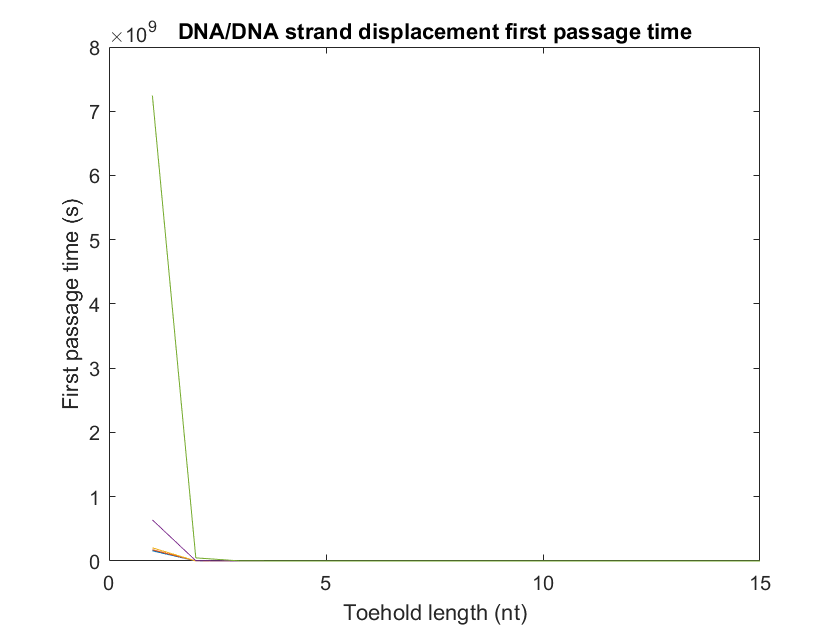

plot(1:15, first_pass_time)
ylabel('First passage time (s)')
xlabel('Toehold length (nt)')
title('DNA/DNA strand displacement first passage time')

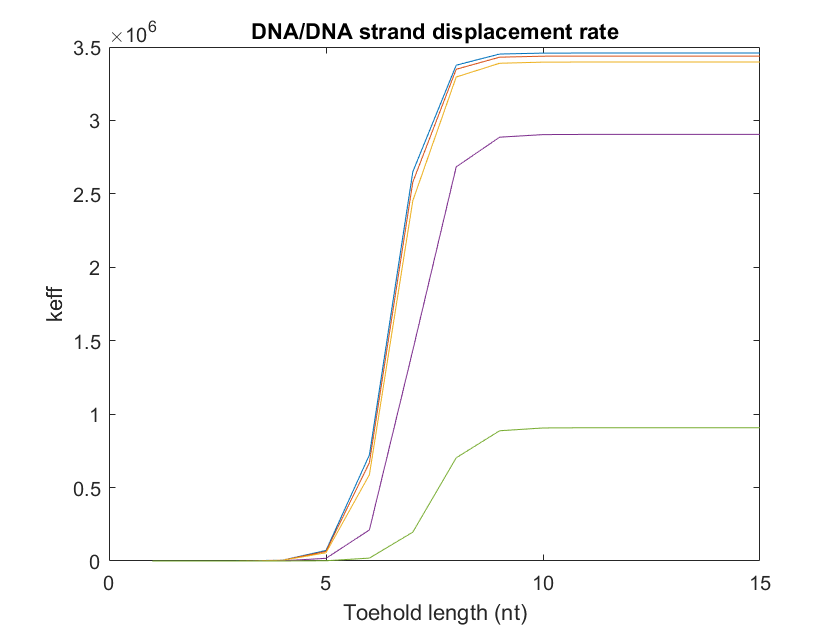


plot(1:15, k_eff)
xlabel('Toehold length (nt)')
ylabel('keff')
title('DNA/DNA strand displacement rate')


ax = gca;
%dark_blue = 1/255*[31,120,180];
%medium_blue = 1/255*[95, 141, 211]
%light_blue  = 1/255*[146,197,222];
%rred = 1/255*[202,0,32];
%maroon = 1/255*[170, 0, 0]
%teal = 1/255*[55, 200, 171]
%purple = [0.4940, 0.1840, 0.5560]
%ndigo = 1/255*[198, 175, 233]
%colour = [[rred]; [purple]; [indigo]; [dark_blue]]

blue_1 = 1/255*[22, 45, 82];
blue_2 = 1/255*[38, 68, 156];
blue_3 = 1/255*[44, 125, 205];
blue_5 = 1/255*[162, 220, 239];
blue_4 = 1/255*[110, 186, 239];
blue_6 = 1/255*[190, 215, 225];
colour = [[blue_1]; [blue_2]; [blue_3]; [blue_4]; [blue_5]; [blue_6]]

colour =     0.0863    0.1765    0.3216
    0.1490    0.2667    0.6118
    0.1725    0.4902    0.8039
    0.4314    0.7294    0.9373
    0.6353    0.8627    0.9373
    0.7451    0.8431    0.8824




%map = colormap(autumn(6))
for dG = 1:4
    plot(1:15, log10(k_eff(dG, :)), 'Color', colour(dG, :), 'linewidth', 2)
    hold on
    scatter(1:15, log10(k_eff(dG, :)),[], colour(dG, :),  'filled', 'HandleVisibility', 'off')
end
legend('2nt','3nt', '4nt','5nt', 'location', 'southeast')
ax.LineWidth = 1.5

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [-2 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.YAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [-2 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


ax.XAxis.FontSize = 12

ax =   Axes with properties:

             XLim: [0 15]
             YLim: [-2 7]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


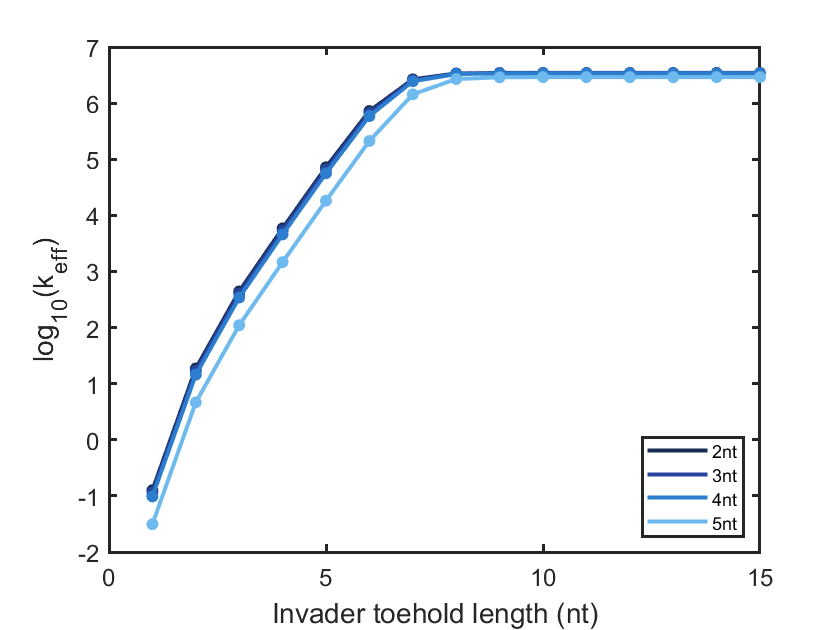

xlabel('Invader toehold length (nt)', 'FontSize', 14)
ylabel('log_1_0(k_e_f_f)', 'FontSize', 14)
hold off 